clc; clear; close all;

%load("montecarlo.mat");
load("montecarlo_tau05.mat")
data

data = Simulink.SimulationData.Dataset 'data' with 8 elements

                         Name                PropagatedName    BlockPath                     
                         __________________  ________________  _____________________________ 
    1  [1x1 Signal]      z                   ''                heave_comp/Calculate setpoint
    2  [1x1 Signal]      zDot                ''                heave_comp/Calculate setpoint
    3  [1x1 Signal]      Position feedbaack  ''                heave_comp/Inertia and load  
    4  [1x1 Signal]      Velocity feedback   ''                heave_comp/Inertia and load  
    5  [1x1 Signal]      Control system:2    Control system:2  heave_comp/To Workspace      
    6  [1x1 Signal]      Transfer Fcn1       Trans

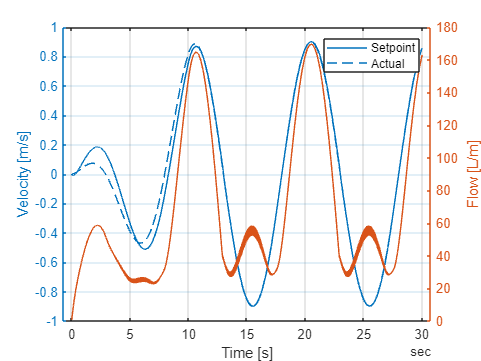


setpoint = data{1}.extractTimetable;
setpointVel = data{7}.extractTimetable;
actual = data{3}.extractTimetable;
actualVel = data{8}.extractTimetable;

flow = data{6}.extractTimetable;

fig1 = figure;
yyaxis left
plot(setpointVel.Time, setpointVel.Variables)
ylabel('Velocity [m/s]')
hold on
grid on
plot(actualVel.Time, actualVel.Variables, '--')
yyaxis right
plot(flow.Time, flow.Variables)
ylabel('Flow [L/m]')
xlabel('Time [s]')
legend('Setpoint', 'Actual')


rms(flow.Variables)

ans = 39.4720

max(flow.Variables)

ans = 169.4389

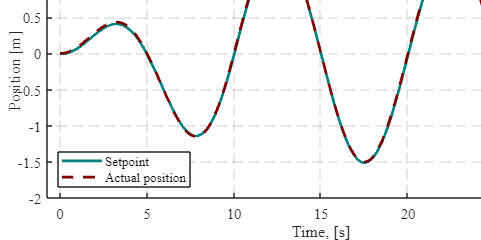


%% Plotting for the repport
W_frame = 16;     % Final width of the frame [cm] of the plot in your document
H_frame = 8;      % Final height of the frame [cm] of the plot in your document
LLC_frame = [5,5];% Position of lower left corner of the frame on the screen [cm]
W_axis = 14.5;    % Width of axis [cm]
H_axis = 6.7;     % Height of axis [cm]
LLC_axis = [1.25, 1.1]; % Position of lower left corner of the axes on the frame [cm]
xlabel_x = W_axis/2;% x-position of the x-label
xlabel_y = -0.6;  % y-position of the x-label [cm]
ylabel_x = -0.6;  % x-position of the y-label [cm]
ylabel_y = H_axis/2;% y-position of the y-label
AxisFontSize = 11;% Font size for axis text in the final plot in your document
LW1 = 1;          % Line width of lines on plot
LW2 = 2;          % Line width of lines on plot
fig = figure;           % Handle for the figure
ax = gca;               % Handle for the axis

fig.Units = 'centimeters';
fig.Position = [LLC_frame W_frame H_frame];


hold on
plt1 = plot(actual.Time, actual.Variables);
plt1.Color = [0 0.502 0.502];%'b';    % y, m, c, r, g, b, w, k,
plt1.LineWidth  = LW2;

plt2 = plot(setpoint.Time, setpoint.Variables);
plt2.Color = [0.5 0 0 1];%'r';
plt2.LineStyle = '--';
plt2.LineWidth = LW2;

ax.Units = 'centimeters';
ax.GridLineStyle = '--';             
ax.Position = [LLC_axis W_axis H_axis];
ax.FontName = 'Times New Roman';
ax.FontSize = AxisFontSize;             % Specified above
%ax.XTick = 0:5:30;                    % Divisions on axes
%ax.YTick = -2:0.5:2;                    % Divisions on axes
%axis([0, 30, -2, 2]);

label_x = xlabel('Time, [s]');
label_x.Units = "centimeters";
label_x.Position = [xlabel_x, xlabel_y];

label_y = ylabel('Position [m]');
label_y.Units = "centimeters";
label_y.Position = [ylabel_x, ylabel_y];

leg = legend('Setpoint', 'Actual position');
leg.Location = "southwest";

hold off
grid on
box on


%filename1 = 'plt_1.eps';
%saveas(fig,filename1, 'epsc');